BLER = estimateBLER_Enhanced_MultiUser(SINR1, SINR2, SINR3, SINR4, SINR5, selected_MCS)

BLER = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


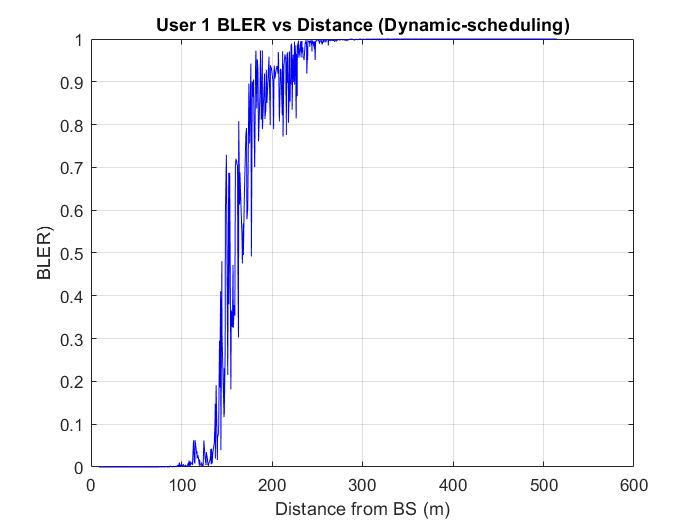

figure; plot(ds, BLER{1}(idx), 'b-'); grid on
xlabel('Distance from BS (m)'); ylabel('BLER)');
title('User 1 BLER vs Distance (Dynamic-scheduling)');

function BLER = estimateBLER_Enhanced_MultiUser(SINR1, SINR2, SINR3, SINR4, SINR5, selected_MCS)
% BLER = estimateBLER_Enhanced_MultiUser(SINR1..SINR5, selected_MCS)
% Inputs:
%   SINRk         : vector (dB) per user k=1..5
%   selected_MCS  : 1x5 cell array; selected_MCS{k}(t) is MCS in [0..14], or -1 for outage
% Output:
%   BLER          : 1x5 cell array; BLER{k}(t) in [0,1]
%
% Model:
%   Logistic BLER "waterfall":  BLER = 1 ./ (1 + exp( steep(m) * (SINR_dB - SNR50(m)) ) )
%   where m = MCS ∈ [0..14]; -1 (outage) → BLER = 1.
%   SNR50(m) ≈ SINR at ~50% BLER for each MCS; tune arrays below for your link setup.

    % ---- sanity ----
    if ~iscell(selected_MCS) || numel(selected_MCS) ~= 5
        error('selected_MCS must be a 1x5 cell array (one MCS vector per user).');
    end

    SINR_all = {SINR1(:), SINR2(:), SINR3(:), SINR4(:), SINR5(:)};
    BLER = cell(1,5);

    % ---- per-MCS logistic parameters (tunable) ----
    % SNR50 in dB: rough working points from very robust (MCS0) to high-rate (MCS14)
    SNR50 = [-8, -6.5, -5, -3.5, -2, -0.5, 1.0,3.0, 5.0, 7.0,10.0, 12.5, 15.0, 17.0, 19.0];       % 64QAM
    % Steepness (larger → sharper waterfall). You can increase slightly with MCS.
    STEEP  = [0.9, 1.0, 1.0, 1.05, 1.1, 1.1, 1.15, 1.2, 1.2, 1.25, 1.3, 1.3, 1.35, 1.35, 1.4];

    for u = 1:5
        s   = SINR_all{u};
        mcs = selected_MCS{u}(:);               % same length as s
        n   = min(numel(s), numel(mcs));        % guard if lengths differ
        s   = s(1:n);  mcs = mcs(1:n);

        bl  = ones(n,1);                        % default BLER=1 (outage/invalid)
        valid = (mcs >= 0) & (mcs <= 14);

        if any(valid)
            m = mcs(valid);                     % 0..14
            % vectorized: BLER = 1/(1+exp(k*(SINR - b)))
            kvec = STEEP(m+1).';
            bvec = SNR50(m+1).';
            bl(valid) = 1 ./ (1 + exp( kvec .* ( s(valid) - bvec ) ));
        end

        % clamp to [0,1]
        bl = max(0, min(1, bl));
        BLER{u} = bl;
    end
end
